# Изучение движения звезд по спектру их излучения

## Инициализация

close all
clear

## Объявление констант

lambdaPr           = 656.28;         % нм
speedOfLight       = 299792.458;     % км/с

angstremChar       = char(197);      % ASCII код ангстрема
textX              = 635;            % нм, позиция подписи к графику по оси Ox
textY              = 3.3 * 10^(-13); % эрг/cм^2/c/ангстрем, позиция подписи к графику по оси Oy

## Импорт данных

spectra     = importdata("spectra.csv");
starNames   = importdata("star_names.csv");
lambdaStart = importdata("lambda_start.csv");
lambdaDelta = importdata("lambda_delta.csv");

## Вычисление количества объектов в выборке

nWavelengths = size(spectra, 1);
nStars       = size(starNames, 1);

## Генерация диапазона длин волн

lambdaEnd = lambdaStart + (nWavelengths - 1) * lambdaDelta;
lambda    = (lambdaStart:lambdaDelta:lambdaEnd)';

## Вычисление Бальмер-альфа

[spectrumsHa, idx] = min(spectra);
lambdasHa          = lambda(idx);

## Вычисление смещения и скорости звезд

z = lambdasHa / lambdaPr - 1;
speed = z * speedOfLight;

## Получение списка имен звезд, удаляющихся от Земли 

movaway = starNames(speed > 0);

## Инициализация графика

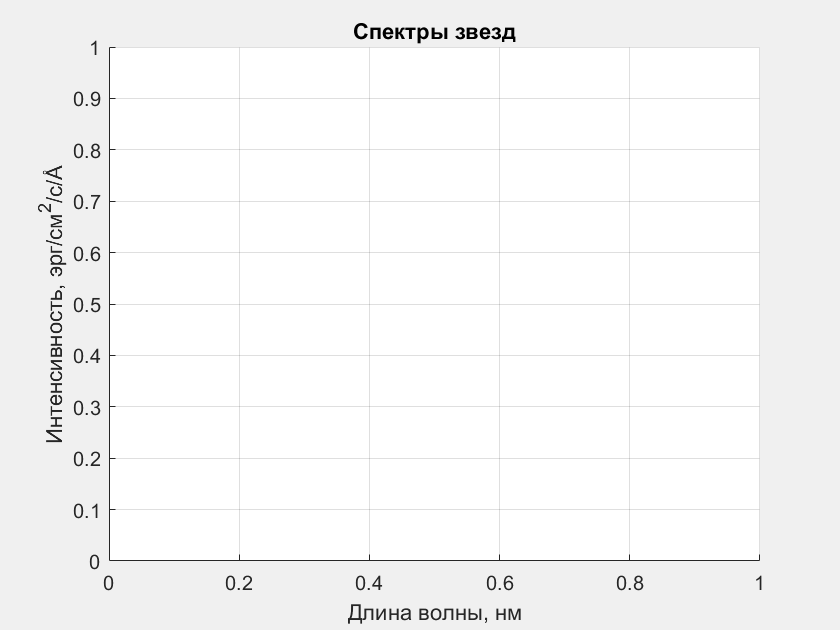

set(gcf, 'Visible', 'on')
grid on
hold on

title('Спектры звезд')
xlabel('Длина волны, нм')
ylabel(strcat('Интенсивность, эрг/cм^2/c/', angstremChar))
text(textX, textY, 'Георгий Лебедев, Б01-008')

## Построение спектров всех звезд

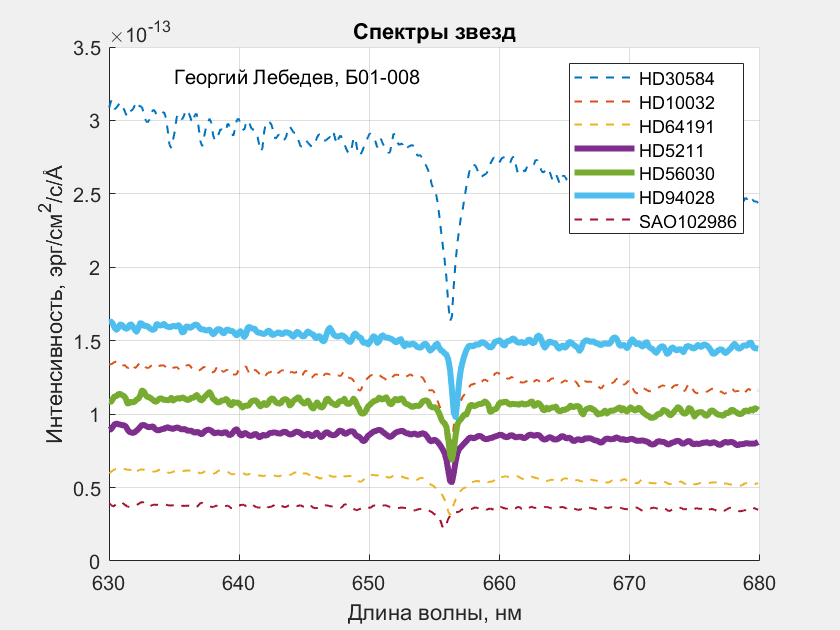

for i = 1:nStars
    if z(i) > 0
        plot(lambda, spectra(:, i), 'LineWidth', 3)
    else
        plot(lambda, spectra(:, i), '--', 'LineWidth', 1)
    end
end

legend(starNames, 'Location', 'northeast');

saveas(gcf, 'спектры.png')
hold off